# Motion-Planner Program Demo

Start by creating the environment.

% Generate a tree obstacle
tree_radius = 4;
tree_height = 40;
tree_x_pos = 10;
tree_y_pos = 10;
tree_z_pos = 0;
tree = create_tree(tree_x_pos, tree_y_pos, tree_z_pos, tree_radius, tree_height);

% generate a Forbidden Zone obstacle
forbidden_zone_length = 20;
forbidden_zone_width = 20;
forbidden_zone_height = 40; % -> will need to update later to make infinity
forbidden_x_pos = 50;
forbidden_y_pos = 50;
forbidden_z_pos = 0;
forbidden_zone = create_forbidden_zone(forbidden_zone_length, forbidden_zone_width, forbidden_zone_height, ...
    forbidden_x_pos, forbidden_y_pos, forbidden_z_pos);

% Create the environment object, and add the obstacles to the environment
env = Environment();
env.add_obstacle(tree);
env.add_obstacle(forbidden_zone);

Now create the aircraft object, which holds onto initial conditions, model parameter, and safety specification information.

% instantiate an Aircraft object
aircraft_x_pos = 0; % in meters
aircraft_y_pos = 0; % in meters
aircraft_z_pos = 30; % in meters
aircraft_heading = deg2rad(45); % in radians
aircraft_aoa = deg2rad(5); % angle of attack in radians
aircraft_detection_radius = 10; % in meters
aircraft_u_max = 5; % in m/s
aircraft_v_max = deg2rad(45); % in radians
aircraft_w_max = deg2rad(15); % in radians
aircraft_max_dist_to_obs = 3; % in meters
aircraft = Aircraft(aircraft_x_pos, aircraft_y_pos, aircraft_z_pos, ...
    aircraft_heading, aircraft_aoa, aircraft_detection_radius, ...
    aircraft_u_max, aircraft_v_max, aircraft_w_max, ...
    aircraft_max_dist_to_obs);

- the Aircraft class is extensible, so if you want to use a different dynamical model for the aircraft (such as a double integrator), then you easily could, then test it within the same environment and with the same controller.

Let's draw the aircraft within the environment to get an idea of where it is.

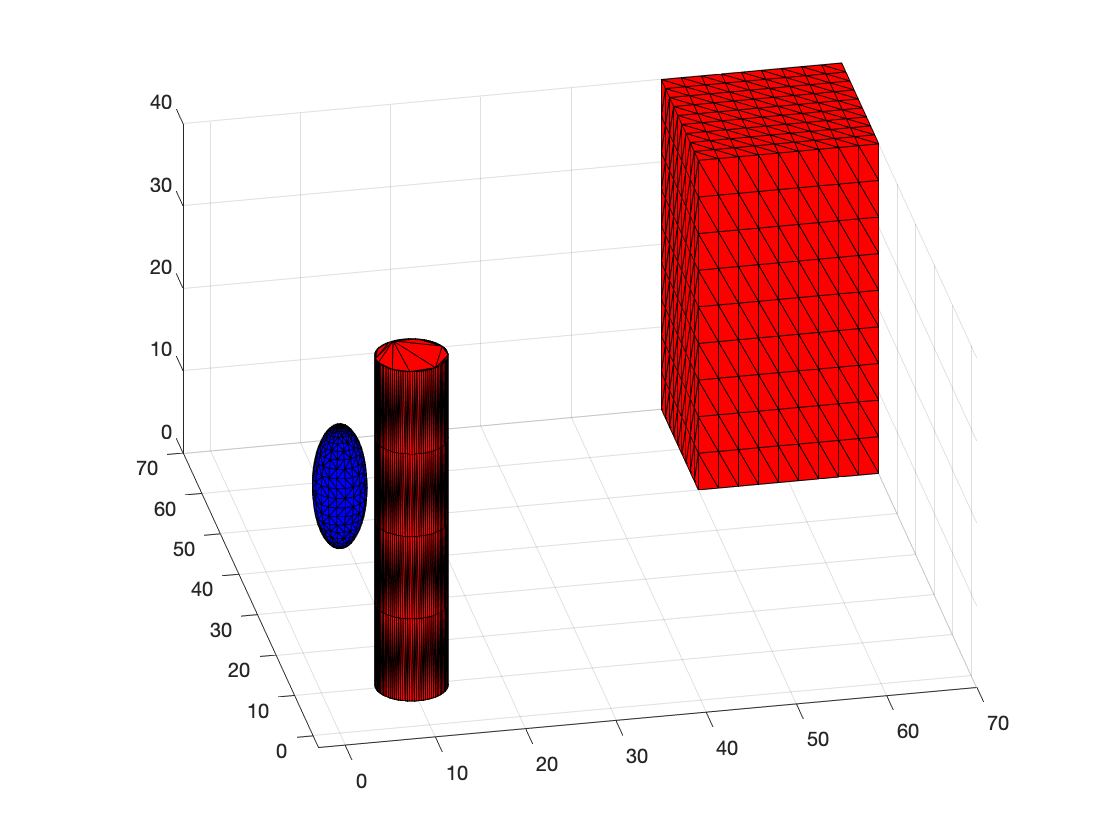

draw(aircraft, env);
view([-11.6 26.6]);

- The blue sphere is the aircraft. The radius represents the safety specification

- The red objects are the unsafe areas

Instantiate an extentable controller object.

% instantiate the "AircraftController" object with default constructor
controller = AircraftController();

- The Controller class is extensible, so if you want to implement another control algorithm (i.e. microscopic (reactive) or macroscopic (global) algorithms), then you easily could and then test it in the same simulation and aircraft model.

Now, create the simulation object, which basically just takes in the environment, aircraft, controller, and the target configuration.

% Simulation
target_x_pos = 80; % in meters
target_y_pos = 80; % in meters
target_z_pos = 10; % in meters
target_abs_tol = 1; % in meters
sim = Simulation(env, aircraft, controller, ...
    [target_x_pos; target_y_pos; target_z_pos], target_abs_tol);

Finally, run the simulation.

tic; sim.simulate(); toc

Elapsed time is 1487.038759 seconds.


Plot and animate the simulation

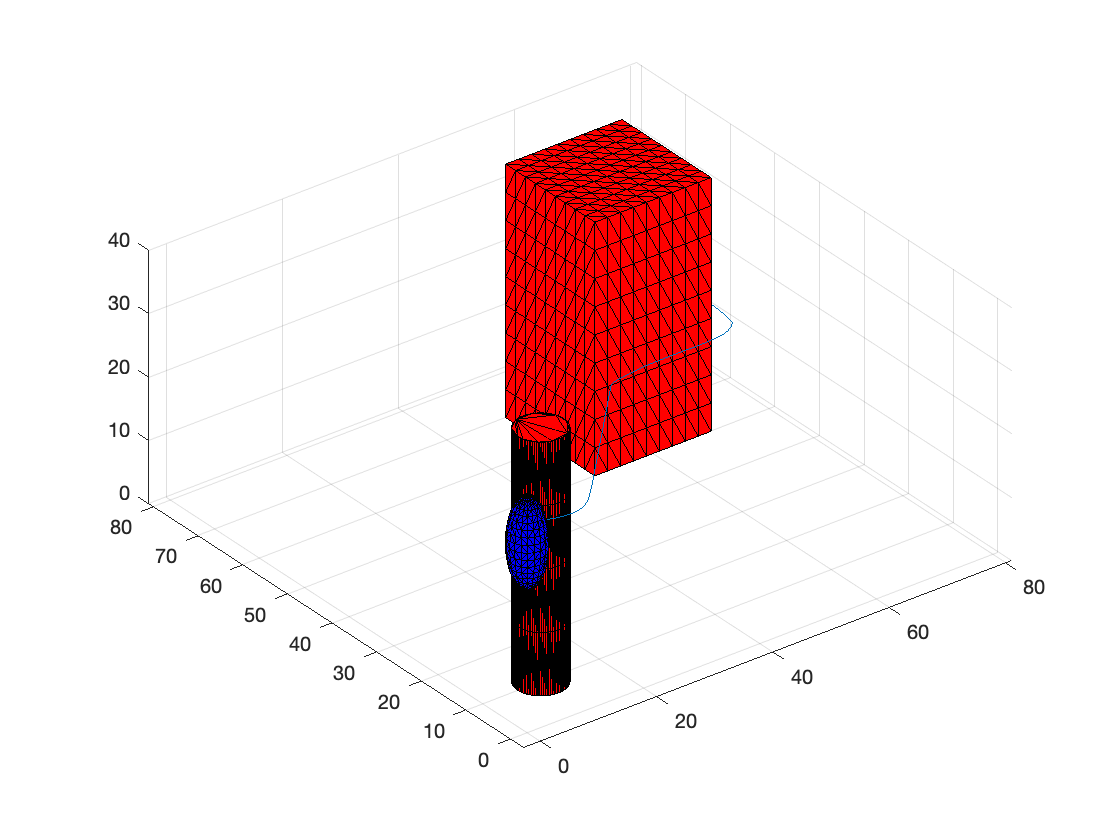

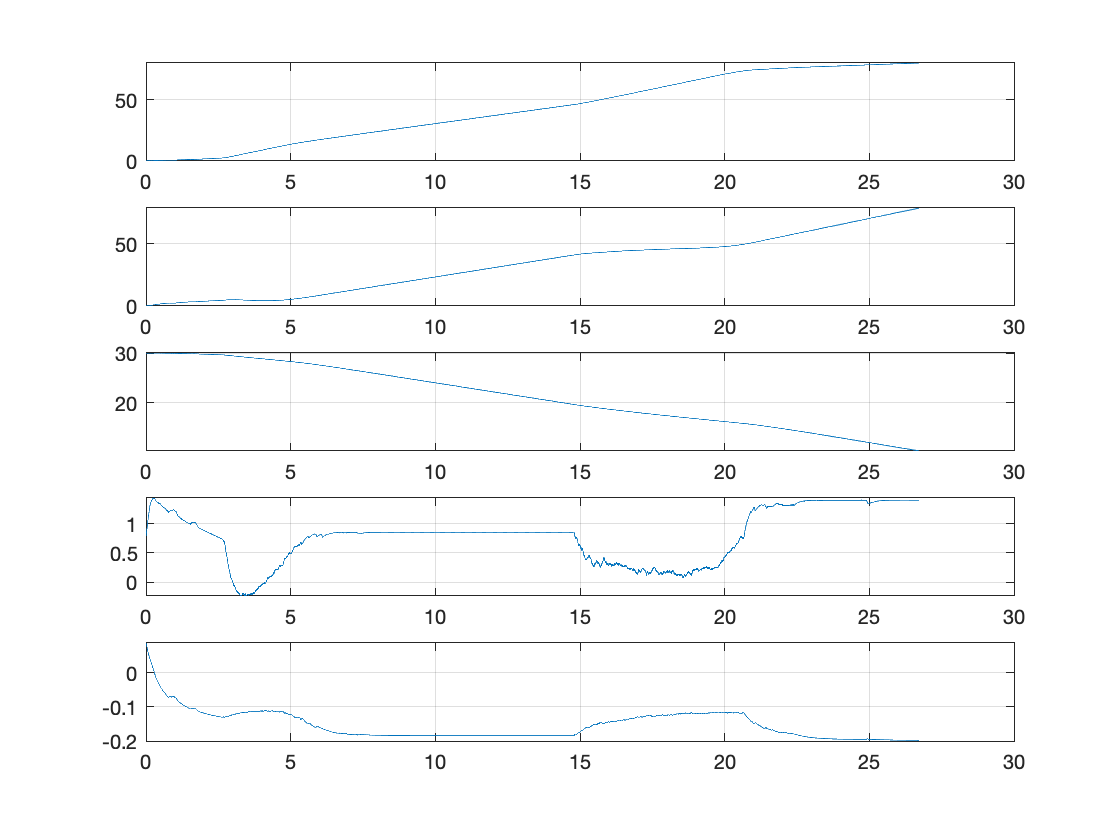

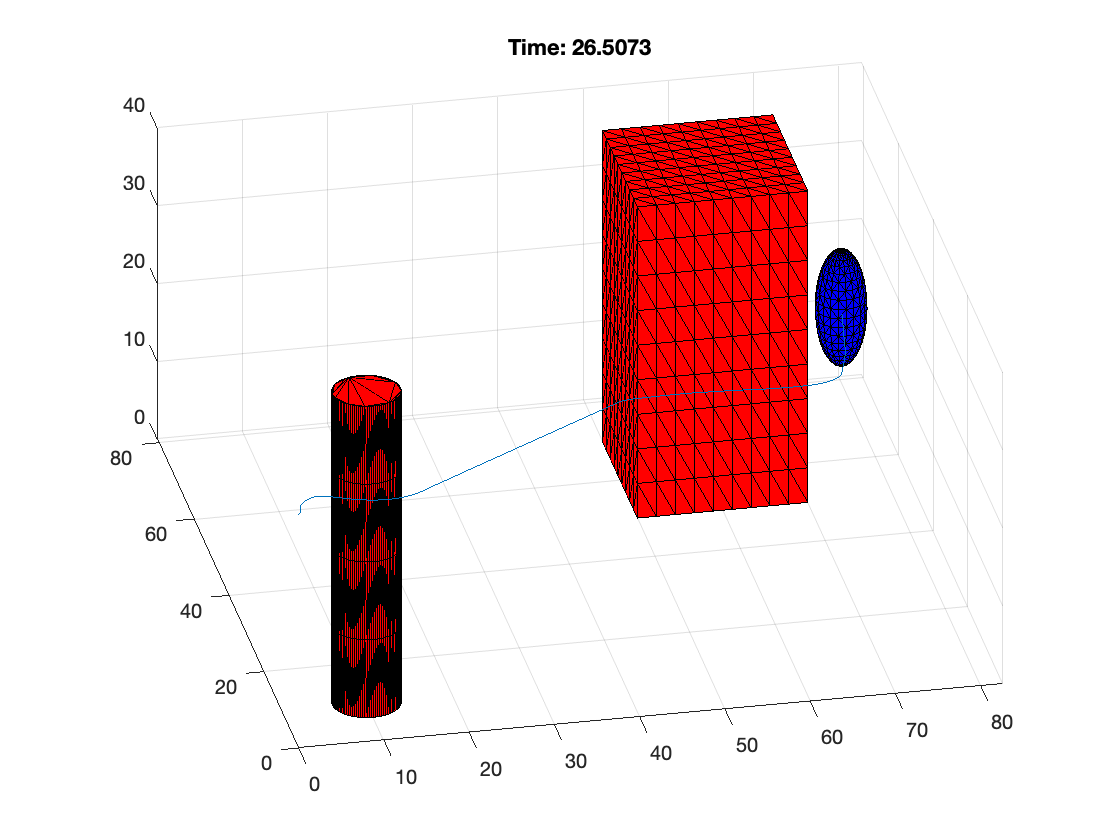

sim.plot();
sim.animate();

Try falsifying the specifications

sim = Simulation(env, aircraft, controller, ...
    [target_x_pos; target_y_pos; target_z_pos], target_abs_tol);
sim.falsify();